# 绘制三维曲面

# 产生平面网格数据<x, y>

% Generate SquareX_matrix & SquareY_matrix

p1.x = 3;
p1.y = 2;
p2.x = 6;
p2.y = 5;
disp(p1);

    x: 3
    y: 2



disp(p2);

    x: 6
    y: 5



%Give the diag of the Square

X = ones(size(p1.y:p2.y))'*(p1.x:p2.x);
Y = (p1.y:p2.y)'*ones(size(p1.x:p2.x));
disp(X);

     3     4     5     6
     3     4     5     6
     3     4     5     6
     3     4     5     6



disp(Y);

     2     2     2     2
     3     3     3     3
     4     4     4     4
     5     5     5     5




disp([X(end) Y(end)] == [p2.x p2.y] & [X(1) Y(1)] == [p1.x p1.y]);

   1   1



use func meshgird(x, y);

[X, Y] = meshgrid(x, y)

Specially , meshgrid(x) equal to meshgrid(x, x)

[X_new, Y_new] = meshgrid(p1.x:p2.x, p1.y:p2.y);
disp(X_new==X)

   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1



disp(Y_new==Y)

   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1



## 使用mesh和surf调用产生三维曲面

mesh(x, y, z, c)

c - for color

surf(x, y, z, c)

Example:


$$z=x^2 -y^{2\;}$$


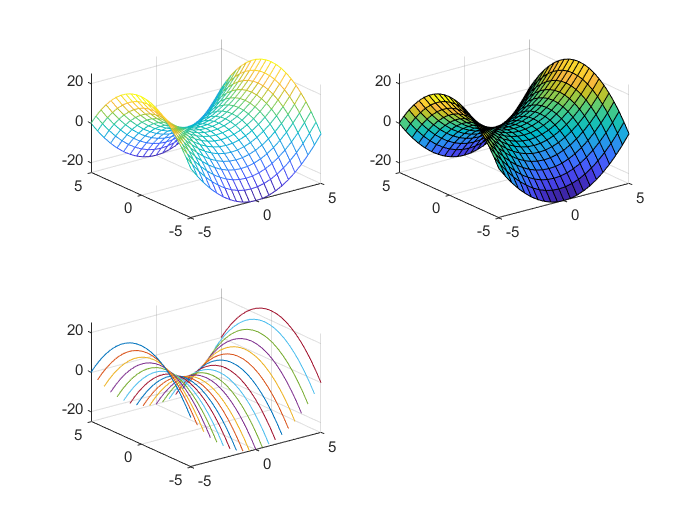

%original boundary
t1 = -5:0.5:5;
[x, y] = meshgrid(t1);
z = x.*x-y.*y;

%Now let's draw it
subplot(2, 2, 1)
mesh(x, y, z);
subplot(2, 2, 2)
surf(x, y, z);
subplot(2, 2, 3)
plot3(x, y, z);
grid on

meshgrid(z, c)

surf(z, c)

当x, y省略时，

[x, y] = meshgrid(1:length(z, 2), 1:length(z, 1))

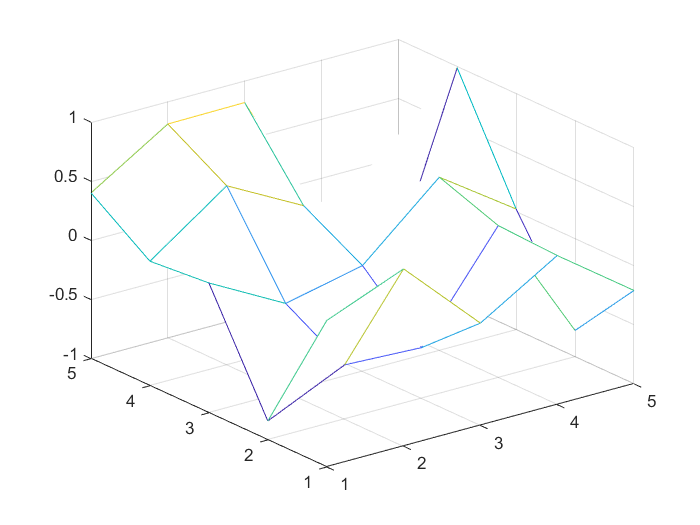

figure

z = rem(randn(5), 1);
%z is a 5x5 matrix
mesh(z);
grid on

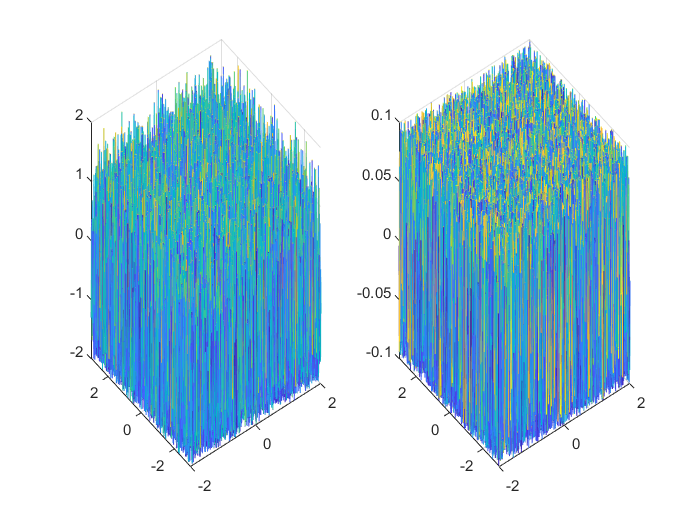

x_range = linspace(-2, 2, 320);
y_range = linspace(-3, 3, 450);
[x, y] = meshgrid(x_range, y_range);

z1 = sin(randn(size(x)))-cos(randn(size(y)));
z2 = rem(z1, 0.1);

subplot(1, 2, 1)
mesh(x, y, z1);

subplot(1, 2, 2)
mesh(x, y, z2);
grid on

## meshc & meshz

meshc带等高线

meshz 带底座

## surfc & surfl

带有等高线

带有光照效果


$$\mathrm{Eg}:z=x^2 +y^{2\;}$$


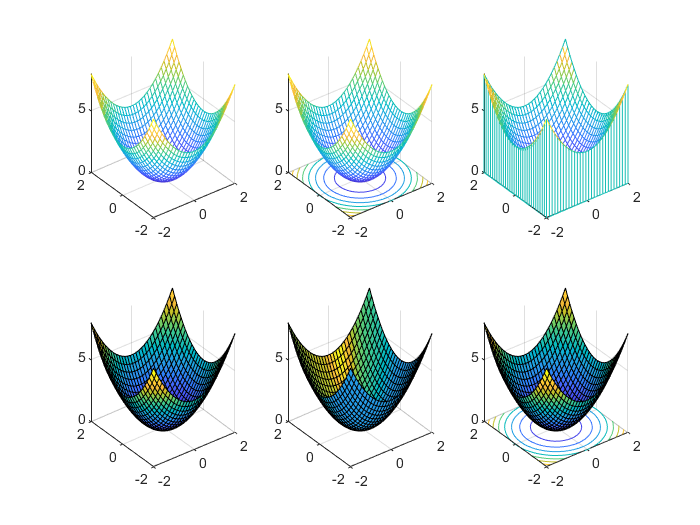

figure
t=linspace(-2, 2, 30);
[x, y] = meshgrid(t);
z = x.*x+y.*y;
subplot(2, 3, 1)
mesh(x, y, z);
subplot(2, 3, 2)
meshc(x, y, z);
subplot(2, 3, 3)
meshz(x, y, z)
subplot(2, 3, 4)
surf(x, y, z)
subplot(2, 3, 5)
surfl(x, y, z)
subplot(2, 3, 6)
surfc(x, y, z)
grid on 

# Part Two: Standard 3D-func

# sphere

[x, y, z]=sphere(n)

x, y, z are both (n+1)x(n+1) matrix

just like

 [x, y] = meshgrid(linspace(-1, 1, n+1))

z = 1-x.*x-y.*y

when you try: sphere() , which equal to sphere(20)

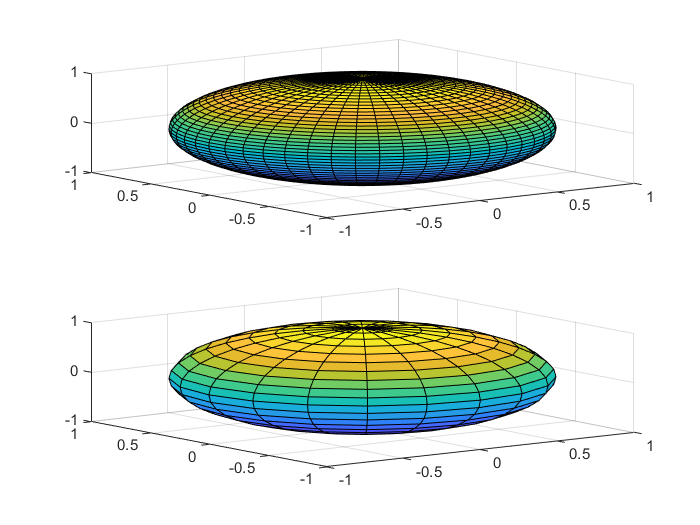

figure
[x1, y1, z1] = sphere(50);
[x2, y2, z2] = sphere(20);
subplot(2, 1, 1)
surf(x1, y1, z1)
subplot(2, 1, 2)
surf(x2, y2, z2)

cylinder()

[x, y, z] =cylinder(R, n)

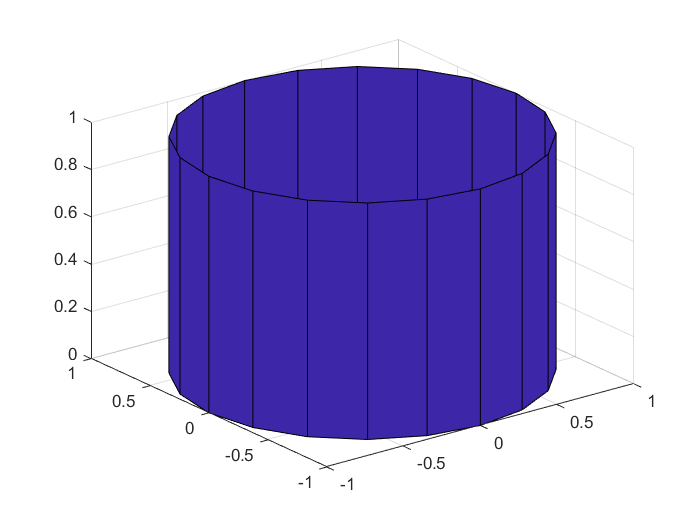

figure 
cylinder

[X,Y,Z] = cylinder 返回半径等于 1 的圆柱的 x、y 和 z 坐标。该圆柱绕其周长有 20 个等距点。

[X,Y,Z] = cylinder(r) 使用 r 定义剖面曲线以返回圆柱的 x、y 和 z 坐标。cylinder 将 r 中的每个元素视为沿圆柱单位高度的等距高度的半径。该圆柱绕其周长有 20 个等距点。

[X,Y,Z] = cylinder(r,n) 基于向量 r 定义的剖面曲线返回圆柱的 x、y 和 z 坐标。该圆柱绕其周长有 n 个等距点。

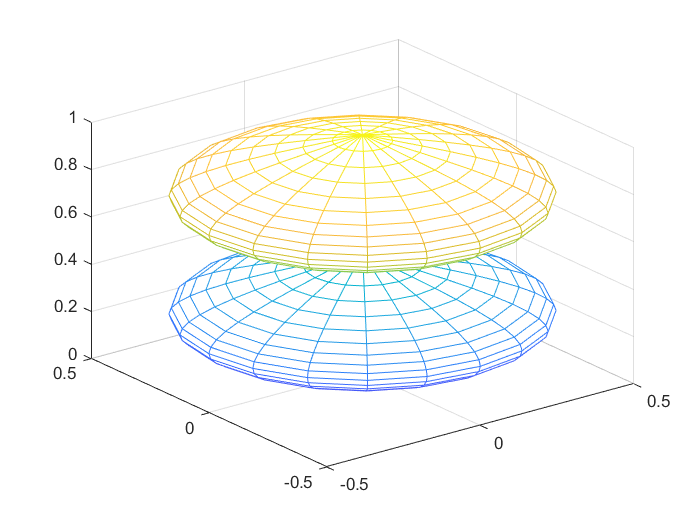

t = (0:0.05:2)*pi;
[x, y, z] = cylinder(sin(t)*0.5);
mesh(x, y, z)

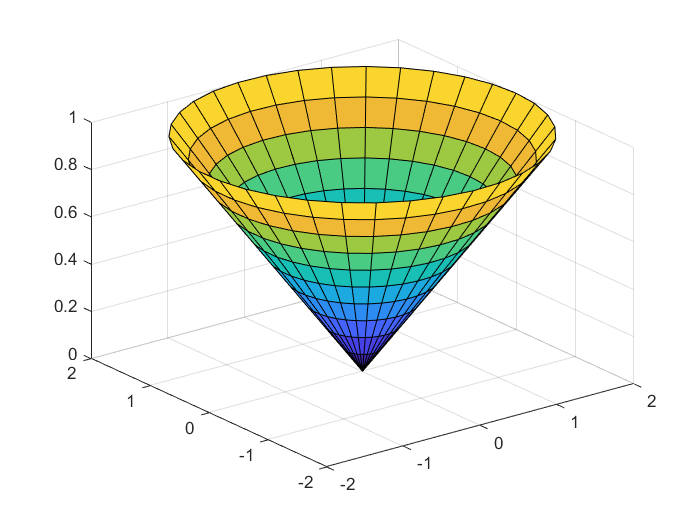

t = 0:0.2:2;
[x, y, z] = cylinder(t, 35);
surf(x, y, z)

## 绘制三维函数式曲面

*fsurf* and **fmesh**

**fmesh(funx, funy, funz, [umin, uMax, vmin, vMax])**


$$\begin{array}{l}
\mathrm{Eg}:\\
x=\mathrm{usinv}\\
y=-\mathrm{ucosv}\\
z=v
\end{array}$$


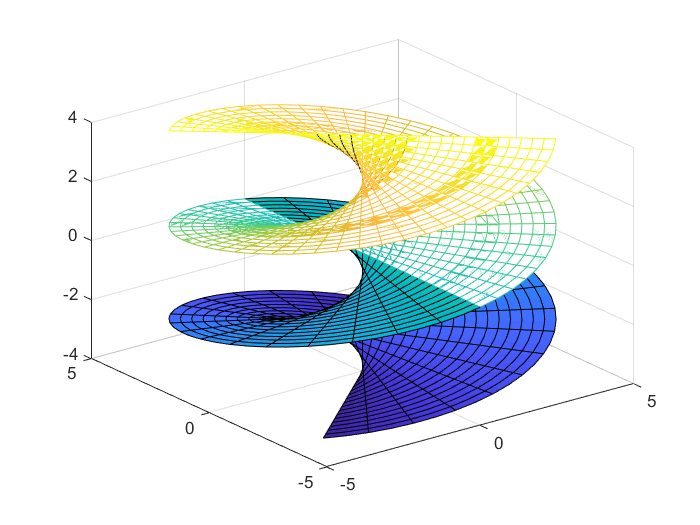

funx = @(u, v) u.*sin(v);
funy = @(u, v) -u.*cos(v);
funz = @(u, v) v;

fsurf(funx, funy, funz, [-5, 5, -4, 4])
hold on
fmesh(funx, funy, funz, [-5, 5, 0, 4])
hold off

# Get a better demonstration

## view()

view(al, el) or view([x y z])

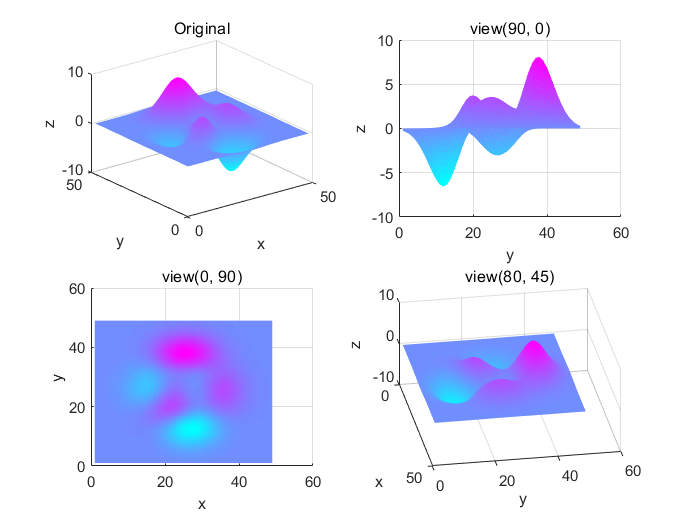




subplot(2, 2, 1)
surf(peaks)
xlabel('x');
ylabel('y');
zlabel('z');
shading interp
colormap('cool');
title('Original')


subplot(2, 2, 2)
surf(peaks)
xlabel('x');
ylabel('y');
zlabel('z');
view(90, 0)
shading flat
colormap('cool');
title('view(90, 0)')

subplot(2, 2, 3)
surf(peaks)
xlabel('x');
ylabel('y');
zlabel('z');
view(0, 90)
shading flat
colormap('cool');
title('view(0, 90)')

subplot(2, 2, 4)
surf(peaks)
xlabel('x');
ylabel('y');
zlabel('z');
view(80, 45)
shading interp
colormap('cool');
title('view(80, 45)')

% another example
figure
cam_vector = [1, 1.41, 2.65];
[x, y] = meshgrid(-3:.1:3);
z = sin(x.*x+y.*y);
colormap('cool')
surf(x, y, z);
shading interp;
xlabel('x');
ylabel('y');
zlabel('z');
[al, el] = view(cam_vector);
fprintf('The cam view is: [%d, %d]', al, el)

The cam view is: [1.446550e+02, 5.688333e+01]

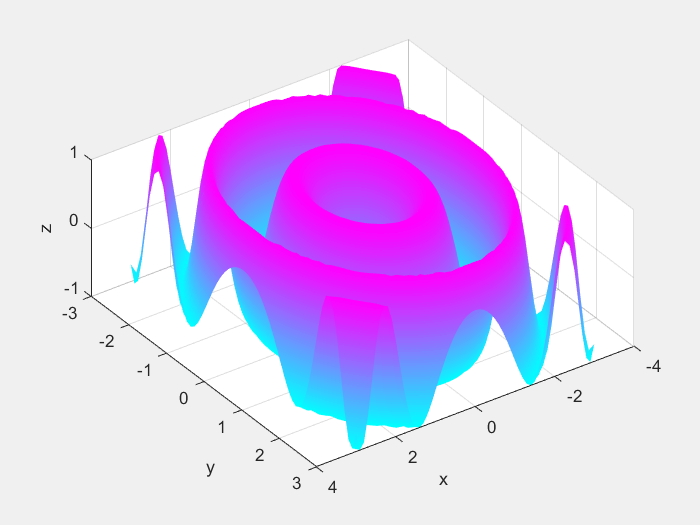

rotate3d on

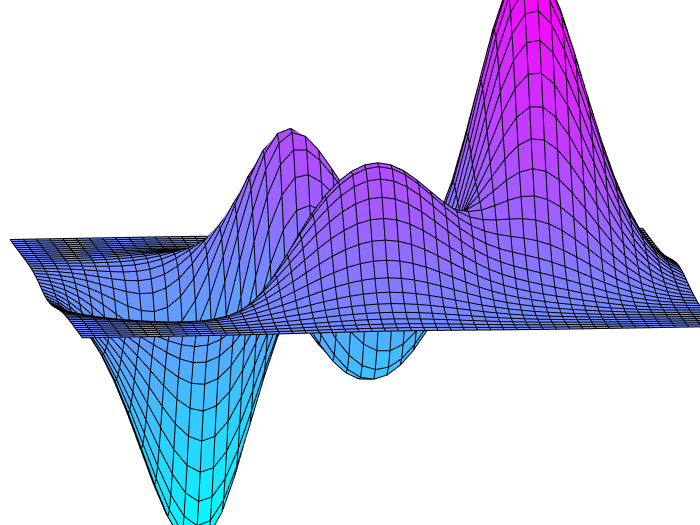

surf(peaks)
axis vis3d off
for x = -200:5:200
    campos([x,5,10])
    drawnow
end